## Generate firing rate figures for TA/trapezoidal tasks

Runs MU pool force matching simulations and plots firing rate figures for them

© 2024 Tiina Murtola/RVC

1. Generate MU pools for TA & task specifications


task_type = 'trapezoidal';
muscle = 'TA';

[task_targets, dt, normFlag] = force_matching_tasks(task_type);

[npools, mups, Fmax] = muscle_MU_settings(muscle, dt);

if normFlag
    task_targets(1,:,1) = Fmax*0.3*task_targets(1,:,1);
    task_targets(2,:,1) = Fmax*0.5*task_targets(2,:,1);
end

load("optim_params_TA_precomp.mat","params")
nx = 2;
ny = 1;

pool_names ={'exp-lin const','exp-lin lin','exp-lin exp','matched-lin const','matched-lin lin','matched-lin exp','mixed-log const','mixed-log lin','mixed-log exp'};


2. Simulate force production, extract true firing rates & plot

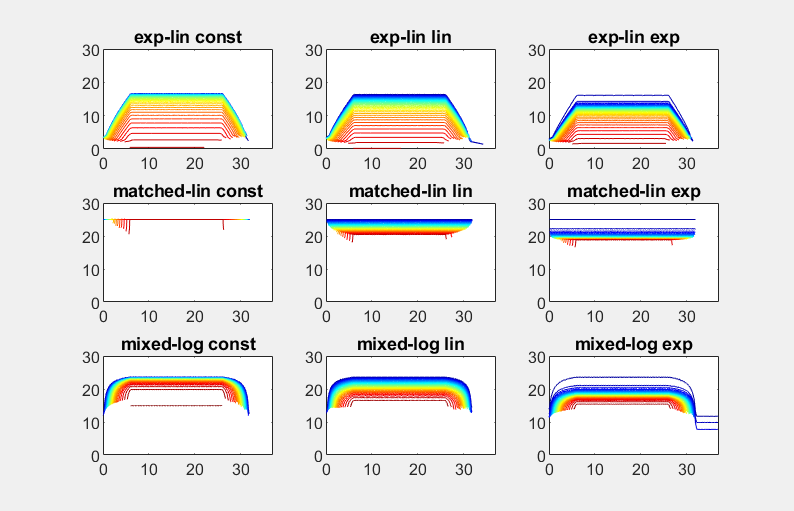

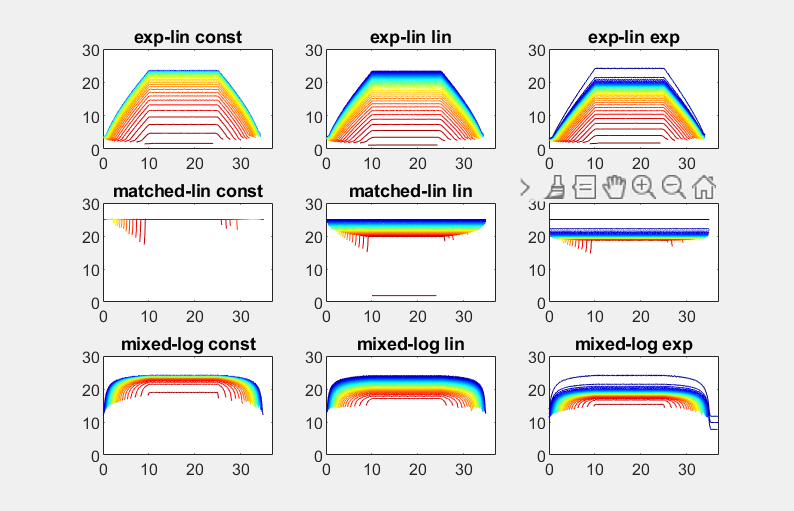

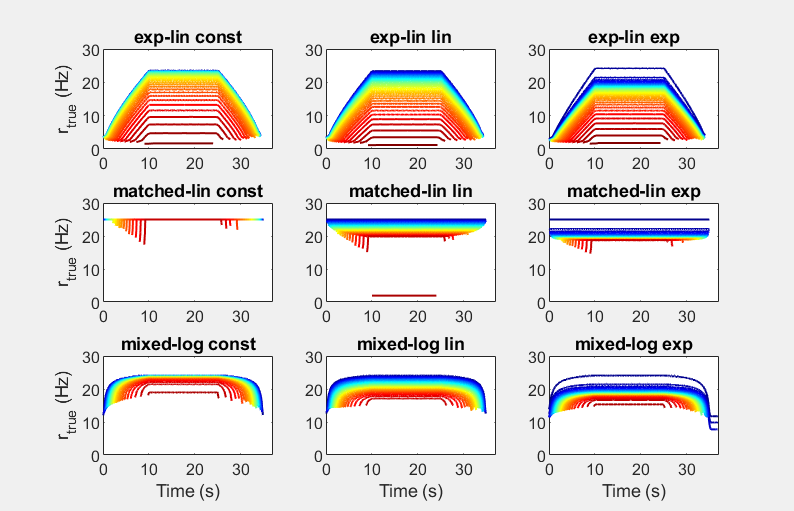


for l = 1:2   % loop through tasks

    force_target = task_targets(l,:,1);
    fvl = task_targets(l,:,2);
    time = (0:length(force_target)-1)*dt;

    drive_signals = [ones(size(force_target));  force_target./fvl];

    figure
    set(gcf,'Visible','on')
    set(gcf,'Units','centimeters')
    set(gcf,'Position',[5 5 14 9])
    for k = 1:npools

        subplot(3,3,k);

        xsol = params(1:nx,k);
        ysol = params(nx+1:nx+ny,k);
        tausol = params(nx+ny+1,k);

        drive = zeros(size(force_target));
        drive(1:end-tausol) = xsol'*drive_signals(:,tausol+1:end).^[1;ysol];

        frs = drive2rate(mups(k),drive);
        u = rate2excitation(mups(k),frs);

        for i = 1:10:mups(k).tot_number
            ind = find(u(i,:));
            if ~isempty(ind)
                frs_inst = 1./diff(ind)/dt;
                plot(time(ind(1:end-1)),smoothdata(frs_inst,'movmean',5))
                hold on
            end
        end

        ylim([0 30])
        xlim([0 37])
        title(pool_names{k})
        h = findobj(gca,'Type','line');
        colororder(gca,jet(length(h)))
    end

    % add some labels
    for i = [1 4 7]
        subplot(3,3,i)
        ylabel('r_{true} (Hz)')
    end
    for i = [7 8 9]
        subplot(3,3,i)
        xlabel('Time (s)')
    end

end


3. Load experimental data and plot firing rate figures for comparison

to use: 

- dowload data from Caillet et al 2023 [https://www.eneuro.org/content/10/9/ENEURO.0064-23.2023](https://www.eneuro.org/content/10/9/ENEURO.0064-23.2023)

- specify path to data (Final_datasets_256) in the filepath-variable

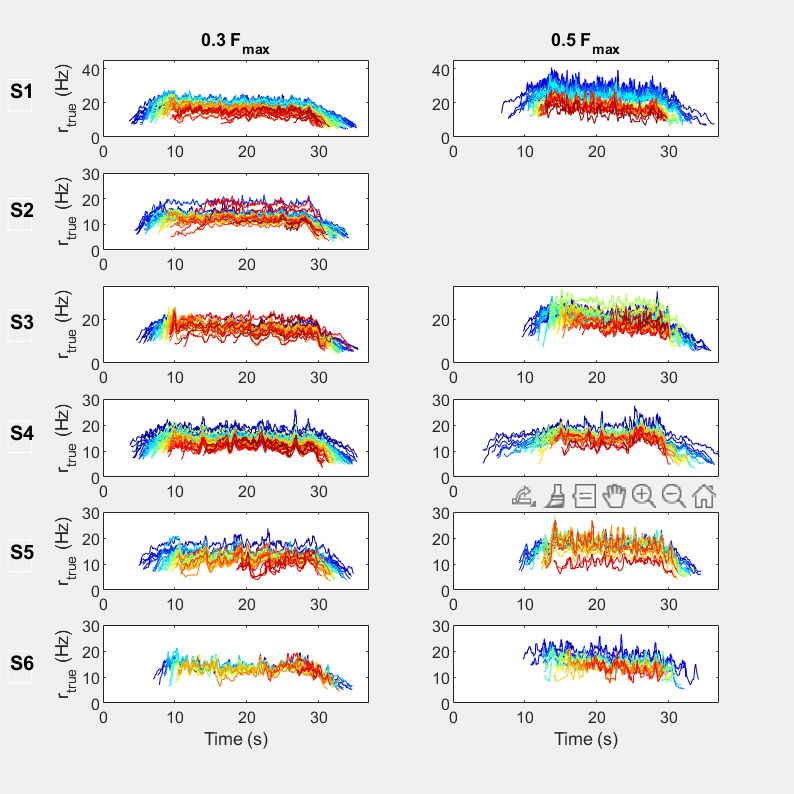



filepath = 'PROCESSED_256_CHANNELS\Final_datasets_256';
files = {'S1_30MVC', 'S1_50MVC', 'S2_30MVC', 'S3_30MVC', 'S3_50MVC','S4_30MVC', 'S4_50MVC', 'S5_30MVC', 'S5_50MVC','S6_30MVC', 'S6_50MVC'};
target = repmat([.3 .5],1,6);       % force target
target(4) = [];                     % remove due to missing S2_50MVC

use_data = 1:11;                    % 1:11 for all data

for i = 1:length(use_data)
    if i == 1
        S = load(fullfile(filepath,[files{use_data(i)} '.mat']));
    else
        S(i) = load(fullfile(filepath,files{use_data(i)}));
    end
end

for i = 1:length(use_data)

    S(i).time = (0:length(S(i).ref_signal)-1)./S(i).fsamp;

    nmu = size(S(i).MUPulses,2);        % number of MUs in data

    u = zeros(nmu,length(S(i).time));   % initialise excitation signals
    first_spike = nan(nmu,1);           % storage for time (sample) of first spike for each MU

    for j = 1:nmu
        u(j,S(i).MUPulses{j})=1;
        first_spike(j) = S(i).MUPulses{j}(1);
    end
    S(i).u = u;
    S(i).first_spike = first_spike;
end

axind = [1 2 3 5 6 7 8 9 10 11 12];
figure
set(gcf,'Visible','on')
set(gcf,'Units','centimeters')
set(gcf,'Position',[5 2 14 14])

for i = 1:length(use_data)
    
    subplot(6,2,axind(i));

    [~,sortind] = sort(S(i).first_spike);    % order of recruitment
    for j = 1:size(S(i).u,1)
        ind = find(S(i).u(sortind(j),:));
        if ~isempty(ind)
            frs_inst = 1./diff(ind)*S(i).fsamp;

            plot(S(i).time(ind(1:end-1)),smoothdata(frs_inst,'movmean',5))
            hold on

            xlim([0 37])
            ylim([0 30])
        end
    end
    newcolors = jet(length(sortind));
    colororder(gca,newcolors)

end

% add labels and axis scales
subplot(6,2,1)
ylim([0 45])
subplot(6,2,2)
ylim([0 45])
subplot(6,2,5)
ylim([0 35])
subplot(6,2,6)
ylim([0 35])

for i = 1:2:11
    subplot(6,2,i)
    ylabel('r_{true} (Hz)');
end
for i = [11 12]
    subplot(6,2,i)
    xlabel('Time (s)');
end

subplot(6,2,1)
title('0.3 F_{max}');
subplot(6,2,2)
title('0.5 F_{max}');

s1 = annotation('textbox',[0.01 0.86 0.03 0.04],'string', 'S1', 'EdgeColor',[1 1 1], 'Margin',1, 'FontWeight','bold');
s2 = annotation('textbox',[0.01 0.71 0.03 0.04],'string', 'S2', 'EdgeColor',[1 1 1], 'Margin',1, 'FontWeight','bold');
s3 = annotation('textbox',[0.01 0.57 0.03 0.04],'string', 'S3', 'EdgeColor',[1 1 1], 'Margin',1, 'FontWeight','bold');
s4 = annotation('textbox',[0.01 0.43 0.03 0.04],'string', 'S4', 'EdgeColor',[1 1 1], 'Margin',1, 'FontWeight','bold');
s5 = annotation('textbox',[0.01 0.28 0.03 0.04],'string', 'S5', 'EdgeColor',[1 1 1], 'Margin',1, 'FontWeight','bold');
s6 = annotation('textbox',[0.01 0.14 0.03 0.04],'string', 'S6', 'EdgeColor',[1 1 1], 'Margin',1, 'FontWeight','bold');



%B = annotation('textbox',[0.74 0.9 0.1 0.1],'string','B)','FitBoxToText','on','Margin',1,'EdgeColor',[ 1 1 1]);
